Si vuole realizzare l'enhancement dell'immagine test image.png. Nello script ex1.m, dopo aver visualizzato l'immagine, individuate i difetti che la caratterizzano, ed effettuate quindi tutte le elaborazioni che vi sembrano opportune per migliorarne la visualizzazione. Infi�ne, ridimensionate l'immagine in modo che abbia dimensioni 512 x 512 (utilizzate un'interpolazione bilineare).

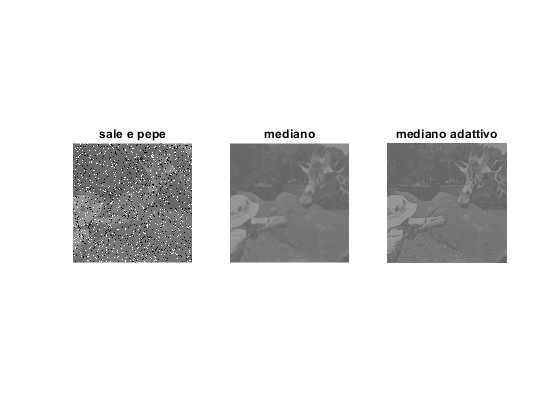

close all; clear all;

x = double(imread('test_image.png'));

% Filtro mediano
y1 = medfilt2(x,[5 5],'symmetric');

% Filtro mediano adattivo
M = colfilt(x,[5 5],'sliding',@max);
m = colfilt(x,[5 5],'sliding',@min);
med = colfilt(x,[5 5],'sliding',@median);
mask = double((x==M) | (x==m));
y2 = med.*mask + x.*(1-mask);

% Ridimensionamento
[M,N] = size(x);
[n,m] = meshgrid(1:N,1:M);
[np,mp] = meshgrid(1:1/2:N+1/2,1:1/2:M+1/2);
y_r = interp2(n,m,y2,np,mp,'bilinar');

% Visualizzazione
figure; 
subplot(131); imshow(x,[0 255]); title('sale e pepe');
subplot(132); imshow(y1,[0 255]); title('mediano');
subplot(133); imshow(y2,[0 255]); title('mediano adattivo');

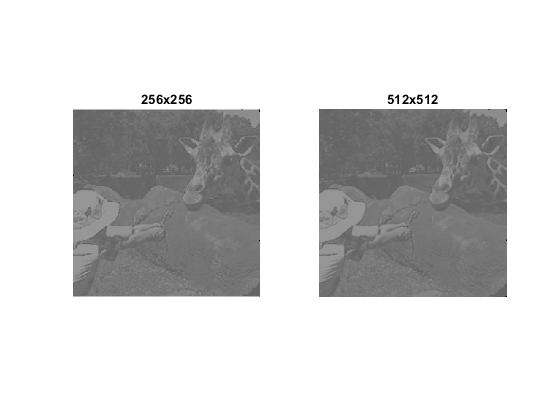


figure; 
subplot(121); imshow(y2,[0 255]); title('256x256');
subplot(122); imshow(y_r,[0 255]); title('512x512');